clc
clear 
Ts = 1/5;
quad = Quad(Ts);
[xs, us] = quad.trim();
sys = quad.linearize(xs, us);
[sys_x, sys_y, sys_z, sys_yaw] = quad.decompose(sys, xs, us);

System loaded and decomposed to 4 parts.

Next, we design MPC controllers for each subsystem individually. For all controllers, optimization is done over a time horizon of 15. We tune the cost matrix Q to attain the desired settling time requirement. 

% Design MPC controllers
fprintf('\n\nTuning controllers...')



 Tuning controllers...

fprintf('X direction:')

X direction:

mpc_x = MPC_Control_x(sys_x, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...


fprintf('Y direction:')

Y direction:

mpc_y = MPC_Control_y(sys_y, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...


fprintf('Z direction:')

Z direction:

mpc_z = MPC_Control_z(sys_z, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 1...
Iteration 2...
Iteration 3...


fprintf('Yaw:\n')

Yaw:


mpc_yaw = MPC_Control_yaw(sys_yaw, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


Each subsystem is simulated until it converges,

% Simulating the closed-loop system
subsystems = ['x', 'y', 'z', 'yaw'];    % subsystems names
tol = 1e-3;                             % convergence criterion
max_t_settle = 0;                       % maximum settling time of all subsystems
% simulate for each subsystem
for sys_num = 3:4
    fprintf(strcat('\nSimulating subsystem ', '\t', subsystems(sys_num)))
    
    % set initial condition
    if(sys_num == 4)                    % initial condition for angle
        x0 = [0; 45];                   % stationary at 45 degree
    else
        x0 = [0; 2];                    % stationary at 2m from origin
    end
    sol.x(:,1) = x0;
    
    % select controller
    switch sys_num
        case 1
            mpc_cont = mpc_x;
        case 2
            mpc_cont = mpc_y;
        case 3
            mpc_cont = mpc_z;
        case 4
            mpc_cont = mpc_yaw;
        otherwise
            fprintf('[Error] subsystem number out of range.')
    end
    
    % simulate at each time step
    i = 1;
    try
        while norm(sol.x(:,end)) > tol  % Simulate until convergence
            % Solve MPC problem for current state
            uopt = mpc_cont.get_u(sol.x(:,i));   
            % Extract the optimal input
            sol.u(:,i) = uopt;
            % Apply the optimal input to the system
            sol.x(:,i+1) = mpc_cont.A*sol.x(:,i) + mpc_cont.B*sol.u(:,i);
            % Go to next time step
            i = i + 1;
        end
    catch
        error('---> Initial state is outside the feasible set <---\n');
    end
    
    % find settling time
    settled = prod(abs(sol.x)<=0.5, 1);     % settled[i] = 1 iff all states are settled at index i
    settled = find(settled);                % indexes when all states are settled
    t_settle = Ts * settled(1);             % settling time in seconds
    max_t_settle = max(max_t_settle, t_settle); % update maximum settling time
    fprintf(strcat('Settling time for this subsystem = ', num2str(t_settle)));
    
    % save results
    switch sys_num
        case 1
            solution.x = sol;
            settling_time.x = t_settle;
        case 2
            solution.y = sol;
            settling_time.y = t_settle;
        case 3
            solution.z = sol;
            settling_time.z = t_settle;
        case 4
            solution.yaw = sol;
            settling_time.yaw = t_settle;
        otherwise
            fprintf('[Error] subsystem number out of range.')
    end
    
    fprintf(strcat('\nMaximum settling time of all subsystems = ' + num2str(max_t_settle)));
end


Simulating subsystemz

Settling time for this subsystem =2

 ª§R¥¦¦ R¦R¡RR¥§¥«¥¦¥RoR


Simulating subsystemy

Settling time for this subsystem =2

 ª§R¥¦¦ R¦R¡RR¥§¥«¥¦¥RoR

Plot the applied input and states.

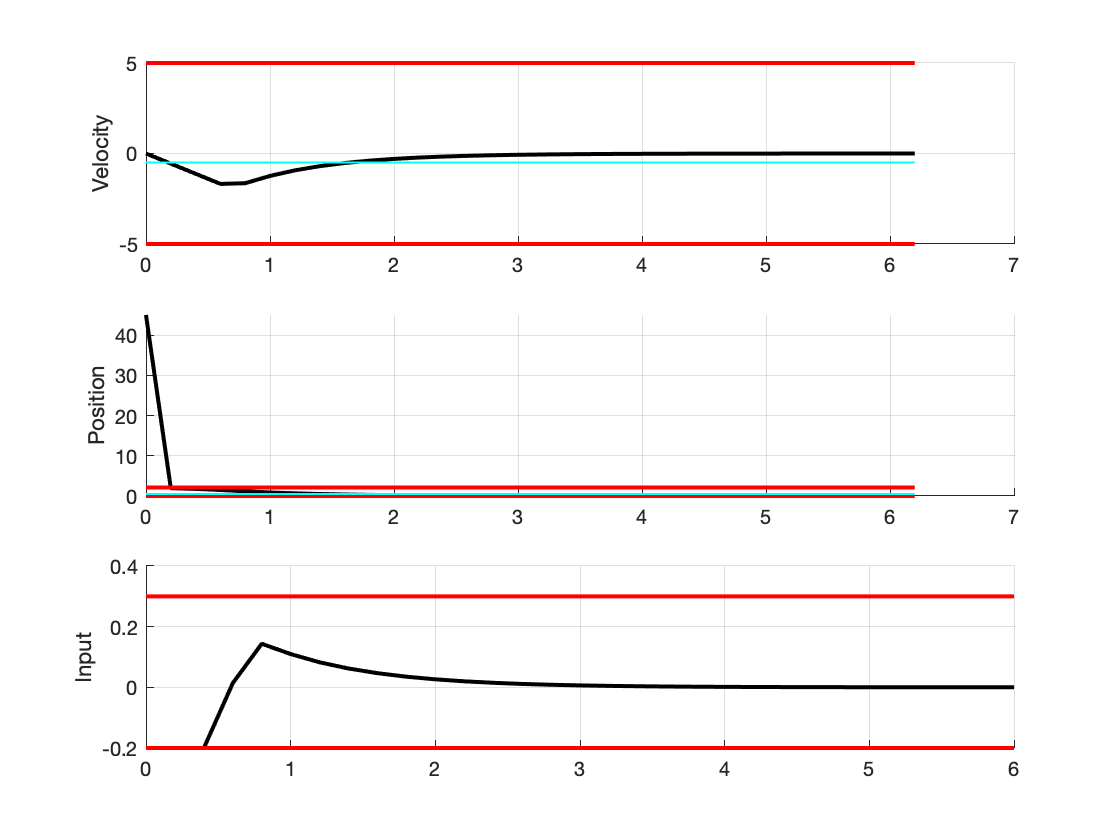

for sys_num = 1:4
    figure
    hold on; grid on;
    
    times = 0: Ts: Ts * (size(sol.x,2)-1);
    o = ones(1,size(sol.x,2));
    
    subplot(3,1,1)
    hold on; grid on;
    plot(times, sol.x(1,:),'-k','markersize',20,'linewidth',2);
    plot(times,5*o,'r','linewidth',2)
    plot(times,-5*o,'r','linewidth',2)
    plot(times,-0.5*o,'c','linewidth',1)
    ylabel('Velocity')
    
    subplot(3,1,2)
    hold on; grid on;
    plot(times, sol.x(2,:),'-k','markersize',20,'linewidth',2);
    plot(times,2.1*o,'r','linewidth',2)
    plot(times,0*o,'r','linewidth',2)
    plot(times,0.5*o,'c','linewidth',1)
    ylabel('Position')
    
    subplot(3,1,3)
    o = ones(1,size(sol.u,2));
    hold on; grid on;
    plot(times(1:end-1), sol.u,'k','markersize',20,'linewidth',2);
    plot(times(1:end-1), 0.3*o,'r','linewidth',2)
    plot(times(1:end-1), -0.2*o,'r','linewidth',2)
    ylabel('Input')
end